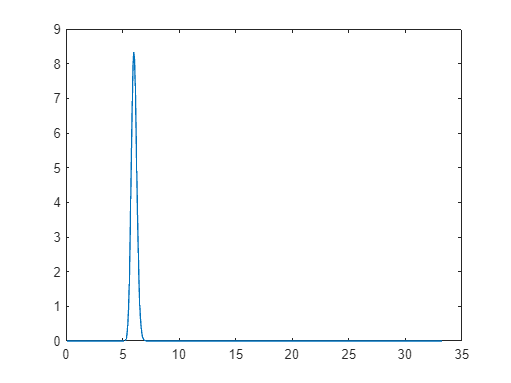

% clc;
% clear all;
% close all;
A=6;
n=sqrt(A);
L_0=5*10^-9;
E_g=1.43;
me_eff=0.067;
mh_eff=0.45;
m_0=9.1093837*10^(-31);
hbar=1.0545718*10^(-34);
mu=1/(1/(m_0*me_eff)+1/(m_0*mh_eff));
q=1.60217663*10^-19;
photon_energy=linspace(1.45,10,500);
x=photon_energy-E_g;
eta=sqrt((2*mu*L_0^2*x*q)/(pi^2*hbar^2));
Reduced_energy=eta.^2;
xeta_0=0.02;
relative_absorption_0=(1/(xeta_0*n.^2)).*exp((-(n./eta-1).^2)./(2*xeta_0^2));
superposition0=superposition0+relative_absorption_0;

xeta_1=0.04;
relative_absorption_1=(1/(xeta_1*n.^2)).*exp((-(n./eta-1).^2)./(2*xeta_1^2));
superposition1=superposition1+relative_absorption_1;

xeta_2=0.10;
relative_absorption_2=(1/(xeta_2*n.^2)).*exp((-(n./eta-1).^2)./(2*xeta_2^2));
superposition2=superposition2+relative_absorption_2;

xeta_3=0.20;
relative_absorption_3=(1/(xeta_3*n.^2)).*exp((-(n./eta-1).^2)./(2*xeta_3^2));
superposition3=superposition3+relative_absorption_3;

plot(Reduced_energy,relative_absorption_0)

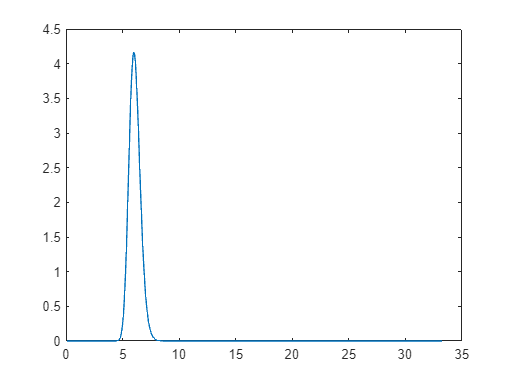

% hold on
plot(Reduced_energy,relative_absorption_1)

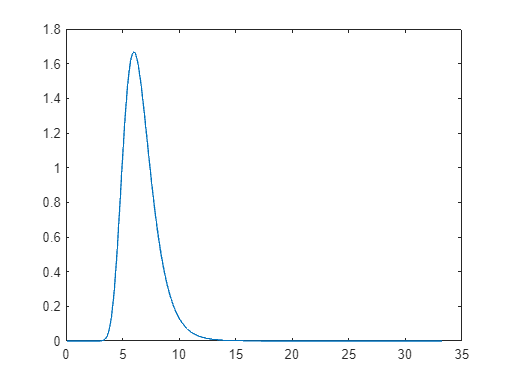

plot(Reduced_energy,relative_absorption_2)

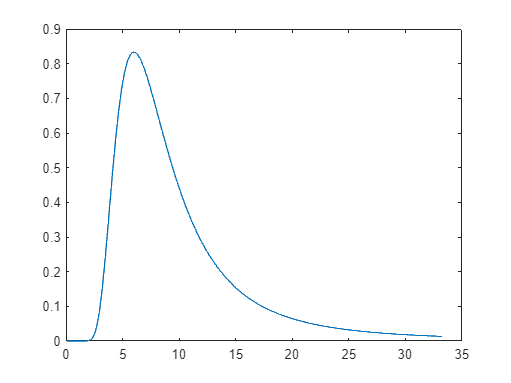

plot(Reduced_energy,relative_absorption_3)
hold off

[maxValue,maxIndex]=max(relative_absorption_0);
maxValue=Reduced_energy(maxIndex);
disp(['maximum relative absorption_0 : ',num2str(maxValue)]);

maximum relative absorption_0 : 5.99


disp(['corresponding Reduced_energy : ',num2str(maxValue)]);

corresponding Reduced_energy : 5.99
